# Taller 1, puntos 1 a 3: perceptron simple y compuertas

clear; close all; clc

## Parametros del modelo

regla      = 3;        % 1: d*x   2: (d-y)*x   3: alpha*(d-y)*x
alpha      = 0.1;
umbral     = 0;
salida     = [-1 1];
max_epocas = 100;
semilla    = 1;

## AND de 2 entradas

[X, d] = compuerta('AND', 2, salida);
[w, b, epocas, convergio] = perceptron(X, d, regla, alpha, umbral, salida, max_epocas, semilla);
epocas, convergio

epocas = 2

convergio = logical
   1


table(X(:,1), X(:,2), d, predecir(X, w, b, umbral, salida), 'VariableNames', {'x1','x2','deseada','modelo'})

ans = 4×4 table
    x1    x2    deseada    modelo
    __    __    _______    ______

    0     0       -1         -1  
    0     1       -1         -1  
    1     0       -1         -1  
    1     1        1          1  


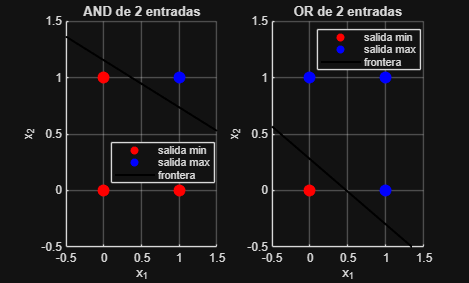


figure
subplot(1,2,1); graficar_frontera(X, d, w, b, umbral, 'AND de 2 entradas');
[X, d] = compuerta('OR', 2, salida);
[w, b] = perceptron(X, d, regla, alpha, umbral, salida, max_epocas, semilla);
subplot(1,2,2); graficar_frontera(X, d, w, b, umbral, 'OR de 2 entradas');

## Reporte 1: las tres reglas en AND y OR de 2, 3 y 4 entradas

Promedio de epocas sobre 20 semillas

compuertas = {'AND','OR'};
entradas = [2 3 4];
semillas = 1:20;
R1 = table();
for c = 1:2
    for n = entradas
        [X, d] = compuerta(compuertas{c}, n, salida);
        for r = 1:3
            ep = zeros(1, 20); conv = ep;
            for s = semillas
                [~, ~, ep(s), conv(s)] = perceptron(X, d, r, alpha, umbral, salida, max_epocas, s);
            end
            R1 = [R1; table(compuertas(c), n, r, mean(ep), min(ep), max(ep), 100*mean(conv), ...
                  'VariableNames', {'Compuerta','Entradas','Regla','Epocas_prom','Epocas_min','Epocas_max','Convergio_pct'})];
        end
    end
end
R1

R1 = 18×7 table
    Compuerta    Entradas    Regla    Epocas_prom    Epocas_min    Epocas_max    Convergio_pct
    _________    ________    _____    ___________    __________    __________    _____________

     {'AND'}        2          1           4.6           2              8             100     
     {'AND'}        2          2           4.8           2              6             100     
     {'AND'}        2          3          4.85           2              7             100     
     {'AND'}        3          1          7.75           2             15             100     
     {'AND'}        3          2          7.95           2             18             100     
     {'AND'}        3          3           7.4           2             14             100     
     {'AND'}        4          1         17.45           4             31             100     
     {'AND'}        4          2         17.95           7             31             100     
     {'AND'}        4          3 

## Reporte 2: efecto de alpha con la regla 3

alphas = [0.01 0.05 0.1 0.3 0.5 1];
R2 = table();
for c = 1:2
    for n = entradas
        [X, d] = compuerta(compuertas{c}, n, salida);
        for a = alphas
            ep = zeros(1, 20);
            for s = semillas
                [~, ~, ep(s)] = perceptron(X, d, 3, a, umbral, salida, max_epocas, s);
            end
            R2 = [R2; table(compuertas(c), n, a, mean(ep), 'VariableNames', {'Compuerta','Entradas','Alpha','Epocas_prom'})];
        end
    end
end
R2

R2 = 36×4 table
    Compuerta    Entradas    Alpha    Epocas_prom
    _________    ________    _____    ___________

     {'AND'}        2        0.01         24.2   
     {'AND'}        2        0.05          6.9   
     {'AND'}        2         0.1         4.85   
     {'AND'}        2         0.3         5.25   
     {'AND'}        2         0.5          4.6   
     {'AND'}        2           1          4.8   
     {'AND'}        3        0.01           18   
     {'AND'}        3        0.05         7.75   
     {'AND'}        3         0.1          7.4   
     {'AND'}        3         0.3          9.1   
     {'AND'}        3         0.5         7.75   
     {'AND'}        3           1         7.95   
     {'AND'}        4        0.01         20.9   
     {'AND'}        4        0.05        14.25   
     {'AND'}        4         0.1           14   
     {'AND'}        4         0.3         15.4   


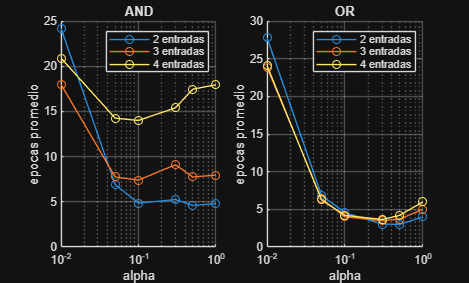


figure
for c = 1:2
    subplot(1,2,c); hold on
    for n = entradas
        k = strcmp(R2.Compuerta, compuertas{c}) & R2.Entradas == n;
        plot(R2.Alpha(k), R2.Epocas_prom(k), '-o', 'DisplayName', sprintf('%d entradas', n));
    end
    set(gca, 'XScale', 'log'); grid on; legend
    xlabel('alpha'); ylabel('epocas promedio'); title(compuertas{c});
end

## Reporte 3: efecto del umbral (2 entradas)

umbrales = [-1 -0.5 0 0.5 1 2];
R3 = table();
for c = 1:2
    [X, d] = compuerta(compuertas{c}, 2, salida);
    for u = umbrales
        ep = zeros(1, 20);
        for s = semillas
            [~, ~, ep(s)] = perceptron(X, d, regla, alpha, u, salida, max_epocas, s);
        end
        R3 = [R3; table(compuertas(c), u, mean(ep), 'VariableNames', {'Compuerta','Umbral','Epocas_prom'})];
    end
end
R3

R3 = 12×3 table
    Compuerta    Umbral    Epocas_prom
    _________    ______    ___________

     {'AND'}        -1           8    
     {'AND'}      -0.5        6.95    
     {'AND'}         0        4.85    
     {'AND'}       0.5         4.1    
     {'AND'}         1         2.8    
     {'AND'}         2         2.4    
     {'OR' }        -1        9.55    
     {'OR' }      -0.5         6.6    
     {'OR' }         0        4.55    
     {'OR' }       0.5         2.4    
     {'OR' }         1        1.95    
     {'OR' }         2         3.3    


## Reporte 4: salida en {0,1} en vez de {-1,1}

Con la regla 1 y d = 0 la correccion es cero, la neurona no aprende esos patrones

R4 = table();
for cod = {[-1 1], [0 1]}
    for c = 1:2
        [X, d] = compuerta(compuertas{c}, 2, cod{1});
        for r = 1:3
            ep = zeros(1, 20); conv = ep;
            for s = semillas
                [~, ~, ep(s), conv(s)] = perceptron(X, d, r, alpha, umbral, cod{1}, max_epocas, s);
            end
            R4 = [R4; table({mat2str(cod{1})}, compuertas(c), r, mean(ep), 100*mean(conv), ...
                  'VariableNames', {'Salida','Compuerta','Regla','Epocas_prom','Convergio_pct'})];
        end
    end
end
R4

R4 = 12×5 table
      Salida      Compuerta    Regla    Epocas_prom    Convergio_pct
    __________    _________    _____    ___________    _____________

    {'[-1 1]'}     {'AND'}       1          4.6             100     
    {'[-1 1]'}     {'AND'}       2          4.8             100     
    {'[-1 1]'}     {'AND'}       3         4.85             100     
    {'[-1 1]'}     {'OR' }       1            3             100     
    {'[-1 1]'}     {'OR' }       2            4             100     
    {'[-1 1]'}     {'OR' }       3         4.55             100     
    {'[0 1]' }     {'AND'}       1          100               0     
    {'[0 1]' }     {'AND'}       2          4.6             100     
    {'[0 1]' }     {'AND'}       3          6.9             100     
    {'[0 1]' }     {'OR' }       1          100               0     
    {'[0 1]' }     {'OR' }       2            3             100     
    {'[0 1]' }     {'OR' }       3         6.85             100     
